# 第6章: 機械学習

本章では，Fabio Gasparetti氏が公開している[News Aggregator Data Set](https://archive.ics.uci.edu/ml/datasets/News+Aggregator)を用い，ニュース記事の見出しを「ビジネス」「科学技術」「エンターテイメント」「健康」のカテゴリに分類するタスク（カテゴリ分類）に取り組む

### 実行環境 

- MATLAB R2020a (Windows 10)

- Text Analytics Toolbox

- Statistics and Machine Learning Toolbox

ここでの結果は問題70でも使うとのことなので、再現性があるように乱数シードを固定しておきます。

clear
rng(0)

## 50. データの入手・整形

[News Aggregator Data Set](https://archive.ics.uci.edu/ml/datasets/News+Aggregator)をダウンロードし、以下の要領で学習データ（`train.txt`），検証データ（`valid.txt`），評価データ（`test.txt`）を作成せよ．

- ダウンロードしたzipファイルを解凍し，`readme.txt`の説明を読む．

- 情報源（publisher）が”Reuters”, “Huffington Post”, “Businessweek”, “Contactmusic.com”, “Daily Mail”の事例（記事）のみを抽出する．

- 抽出された事例をランダムに並び替える．

- 抽出された事例の80%を学習データ，残りの10%ずつを検証データと評価データに分割し，それぞれ`train.txt`，`valid.txt`，`test.txt`というファイル名で保存する．ファイルには，１行に１事例を書き出すこととし，カテゴリ名と記事見出しのタブ区切り形式とせよ（このファイルは後に問題70で再利用する）．

学習データと評価データを作成したら，各カテゴリの事例数を確認せよ．

ダウンロードされた zip を解凍し、`newCorpora.csv` というファイルが同じディレクトリに展開されている想定で進めます。`readme.txt` によると、`newCorpora.csv` には以下の8個の変数が tab 区切りで入っている模様。

[readtable](https://jp.mathworks.com/help/matlab/ref/readtable.html) 関数で読み込みます。デフォルト設定で何とかなりそうです。

data = readtable('newsCorpora.csv');
varNames = ["ID","Title","URL","Publisher","Category","Story","Hostname","TimeStamp"];
data.Properties.VariableNames = varNames;

変数名もちゃんと付けておきます。冒頭だけ眺めてみると以下。

head(data)

ans = 8×8 table
    ID                                       Title                                                                                                      URL                                                                        Publisher          Category                  Story                         Hostname            TimeStamp 
    __    ____________________________________________________________________________    _______________________________________________________________________________________________________________________________    _____________________    ________    _________________________________    _______________________    __________

    1     {'Fed official says weak data caused by weather, should not slow taper'    }    {'http://www.latimes.com/business/money/la-fi-mo-federal-reserve-plosser-stimulus-economy-20140310,0,1312750.story\?track=rss'}    {'Los Angeles Times'}     {'b'}      {'ddUyU0VZz0BRneMioxUPQVP6sIxvM'}    {'www.latimes.com'    

この後使うのは Title・Publisher・Category のみ。それぞれ取り扱いやすいように string 型・string型・カテゴリ型に変えておきます。

data.Category = categorical(data.Category);
data.Publisher = string(data.Publisher);
data.Title = string(data.Title);

### カテゴリ型補足

b = business, t = science and technology, e = entertainment, m = health だと分かりにくいので、変えておきます。

categories(data.Category)

ans = 4×1 の cell 配列
    {'b'}
    {'e'}
    {'m'}
    {'t'}


が現在のカテゴリ一覧。この順であたらしいカテゴリ名を与えて変更します。

data.Category = renamecats(data.Category,["Business","Entertainment","Health","Technology"]);
categories(data.Category)

ans = 4×1 の cell 配列
    {'Business'     }
    {'Entertainment'}
    {'Health'       }
    {'Technology'   }


### 情報源の絞り込み

情報源（publisher）が"Reuters”, “Huffington Post”, “Businessweek”, “Contactmusic.com”, “Daily Mail”の事例（記事）のみを抽出する．

とのことですが、事例（記事）というのは TITLE のことでいいのかな・・いいとします。

`ismember` 関数で進めます。

selected = ["Reuters","Huffington Post","Businessweek","Contactmusic.com","Daily Mail"];
idxSelected = ismember(data.Publisher,selected);
dataSelected = data(idxSelected,["Title","Category"]);
head(dataSelected)

ans = 8×2 table
                                        Title                                        Category
    _____________________________________________________________________________    ________

    "Europe reaches crunch point on banking union"                                   Business
    "ECB FOCUS-Stronger euro drowns out ECB's message to keep rates low for  ..."    Business
    "Euro Anxieties Wane as Bunds Top Treasuries, Spain Debt Rallies"                Business
    "Noyer Says Strong Euro Creates Unwarranted Economic Pressure (1)"               Business
    "REFILE-Bad loan triggers key feature in ECB bank test announcement- sources"    Business
    "UPDATE 1-ECB to reveal bad loan hurdles for euro zone bank test -sources"       Business
    "Central banks must contain threats from low prices: ECB's Noyer"                Business
    "UPDATE 1-Central banks must contain threat from low prices -Noyer"              Business


### 3. 抽出された事例をランダムに並び替え

ここは `randperm` で行きます。順番をランダムに入れ替えたベクトルを返してくれます。

randperm(10)

ans =      6     3     7     8     5     1     2     4     9    10


こんな感じ。なので、`dataSelected` のデータの数を入力して、インデックスとして使えば順番がランダムに入れ替わります。

Ntotal = height(dataSelected);
idxRandom = randperm(Ntotal);
dataRandom = dataSelected(idxRandom,:);

### データ分割

4. 抽出された事例の80%を学習データ，残りの10%ずつを検証データと評価データに分割し，それぞれ`train.txt`，`valid.txt`，`test.txt`というファイル名で保存する．ファイルには，１行に１事例を書き出すこととし，カテゴリ名と記事見出しのタブ区切り形式とせよ（このファイルは後に問題70で再利用する）．

何かそれ用の関数がありそうな気がします（[`cvpartition`](https://jp.mathworks.com/help/stats/cvpartition.html) 関数とか）がここは分かりやすく、ただ単純にそのまま上から順に 80%/10%/10% を取ります。

vars = ["Category","Title"];
Ntrain = Ntotal*0.8;
Nvalid = Ntotal*0.1;
Ntest = Ntotal*0.1;
dataTrain = dataRandom(1:Ntrain,vars);
dataValid = dataRandom(Ntrain+1:Ntrain+Nvalid,vars);
dataTest = dataRandom(Ntrain+Nvalid+1:end,vars);

ファイルへの出力は `writetable` 関数で。`delimiter` で区切り文字を指定しておきます。

writetable(dataTrain,'train.txt');
writetable(dataValid,'valid.txt');
writetable(dataTest,'test.txt');

カテゴリーの分類を見ておきます。

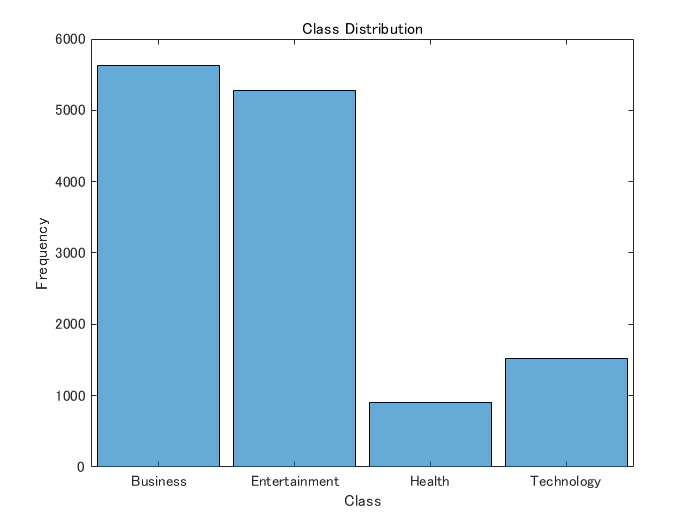

histogram(dataRandom.Category)
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

Health カテゴリ、Science and Technology カテゴリの記事は少ない模様。

分割したそれぞれのデータでの分布も念のため確認。

tabulate(dataTrain.Category)

          Value    Count   Percent
       Business     4503     42.19%
  Entertainment     4219     39.53%
         Health      751      7.04%
     Technology     1199     11.24%


tabulate(dataValid.Category)

          Value    Count   Percent
       Business      574     43.03%
  Entertainment      531     39.81%
         Health       74      5.55%
     Technology      155     11.62%


tabulate(dataTest.Category)

          Value    Count   Percent
       Business      550     41.23%
  Entertainment      529     39.66%
         Health       85      6.37%
     Technology      170     12.74%


大きく外れていないので良し！

## 51. 特徴量抽出

学習データ，検証データ，評価データから特徴量を抽出し，それぞれ`train.feature.txt`，`valid.feature.txt`，`test.feature.txt`というファイル名で保存せよ． なお，カテゴリ分類に有用そうな特徴量は各自で自由に設計せよ．記事の見出しを単語列に変換したものが最低限のベースラインとなるであろう.

ここでは Text Analytics Toolbox のデモコード "[Create Simple Text Model for Classification](https://jp.mathworks.com/help/textanalytics/ug/create-simple-text-model-for-classification.html)" を参考に（マネして）進めます。

### 前処理

まず特徴量抽出の前処理部分ですが、デモコードで使われているものをそのまま活用します。

以下の処理をしています。

- [`tokenizedDocument`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.html) で入力文をトークン化（単語に分割）

- [`removeStopWords`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.removestopwords.html) でand, of, the などのストップワードを削除

- [`normalizeWords`](https://jp.mathworks.com/help/textanalytics/ref/normalizewords.html) で各単語を原型（？）にそろえる

- [`erasePunctuation`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.erasepunctuation.html) でコンマやピリオドなど削除

- [`removeShortWords`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.removeshortwords.html) で 2文字以下の単語を削除

- [`removeLongWords`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.removelongwords.html) で 15 文字以上の単語を削除

最低限のベースラインよりは少しは手が加わっているかな？

documents = preprocessText(dataTrain.Title);

処理結果を原文と比較してみると以下の通り。人間には読みにくいですが。

documents(1:5)

ans =   5×1 tokenizedDocument:

    8 tokens: same engineer design switch 595 million recall car
    9 tokens: hormel foods buy muscle milk product maker cytosport holdings
    5 tokens: beer tour germany lady rock
    7 tokens: murdoch bid boosts carey james jockeys position
    8 tokens: update 2us judge decline order park notice car


dataTrain.Title(1:5)

ans = 5×1 の string 配列
    "Same engineer designed switches on 5.95 million recalled GM cars"
    "Hormel Foods to buy Muscle Milk products maker CytoSport Holdings"
    "Beer Touring in Germany: Who Are These Ladies and How Are They Rocking  ..."
    "Murdoch Bid Boosts Carey as James Jockeys for Position"
    "UPDATE 2-US judge declines to order 'park it now' notices for GM cars"


### Bag of Words

シンプルに文書中に出現する単語を数え、その数を特徴とする手法を使います。 文の中での出現順序は考慮しないシンプルな表現ですが、単語数が多い＝データの次元が膨大になる点には要注意。

bag = bagOfWords(documents)

bag =   bagOfWords のプロパティ:

          Counts: [10672×13133 double]
      Vocabulary: [1×13133 string]
        NumWords: 13133
    NumDocuments: 10672


### おまけの処理

ここで、2 回以下しか登場しない単語（ 3 回以上出てこない）は削除します。その結果、元文章（Title）が空になってしまうデータも一緒に取り除いておく処理をします。

bag = removeInfrequentWords(bag,2);
[bag,idx] = removeEmptyDocuments(bag);
length(idx)

ans = 2

2 つあるみたいですね・・。一応確認しておきます。元タイトルとトークン化後。

dataTrain(idx,:)

ans = 2×2 table
      Category                          Title                    
    _____________    ____________________________________________

    Entertainment    "Who's Paddy?"                              
    Technology       "Don't Undervalue Importance of Co-benefits"


documents(idx,:)

ans =   2×1 tokenizedDocument:

    1 tokens: paddy
    3 tokens: undervalue importance cobenefits


確かに他に出てこないのであれば学習データとしてあまり価値がなさそうですね。削除します。単語数が半分程にまで劇的に減っている点に注目。

dataTrain2 = dataTrain;
dataTrain2(idx,:) = [];
bag

bag =   bagOfWords のプロパティ:

          Counts: [10670×5010 double]
      Vocabulary: [1×5010 string]
        NumWords: 5010
    NumDocuments: 10670


## 52. 学習

51で構築した学習データを用いて，ロジスティック回帰モデルを学習せよ．

ロジスティック回帰ですが、3 個以上のクラス分けなのでマルチクラス モデルの近似を行う [fitcecoc](https://jp.mathworks.com/help/stats/fitcecoc.html) を使用します。デフォルトだと各クラス 1 対 1 分類をする設定で SVM を使うので、その辺はロジスティック回帰を使う用に変えておきます。

XTrain = bag.Counts; % 特徴量
YTrain = dataTrain2.Category; % カテゴリ（応答変数）

% 使用する学習器テンプレート
t = templateLinear('Learner','logistic');
mdl = fitcecoc(XTrain,YTrain,'Learners',t,'Prior',"uniform",'Coding','onevsall')

mdl =   classreg.learning.classif.CompactClassificationECOC
      ResponseName: 'Y'
        ClassNames: [Business    Entertainment    Health    Technology]
    ScoreTransform: 'none'
    BinaryLearners: {4×1 cell}
      CodingMatrix: [4×4 double]


  Properties, Methods


こんなモデルができました。

学習データでの予測精度も見ておきます。

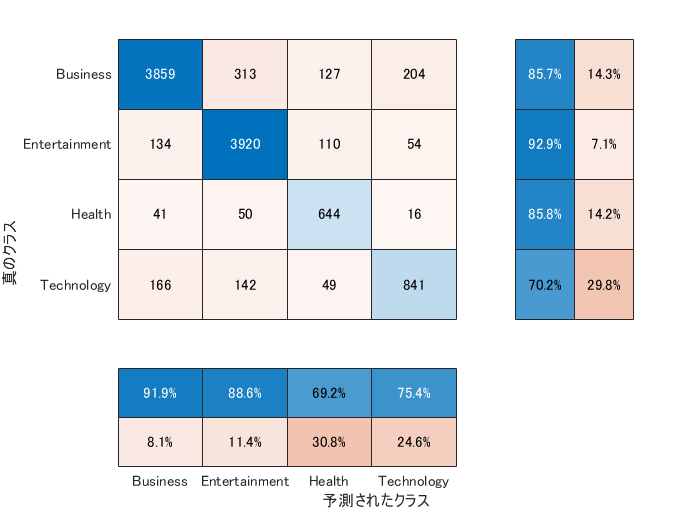

categoryPred = predict(mdl,XTrain);
confusionchart(YTrain, categoryPred, ...
    'ColumnSummary',"column-normalized",...
    'RowSummary',"row-normalized");

それらしい結果となりました。いくつかポイントをまとめます。

### Prior: "uniform"

まず事前確率。これはデフォルトでは学習データ内での各クラスの出現確率に依存する "emperical" という設定になっています。ただ上で見たとおり、学習データが特定のカテゴリに偏っているので、バイアスなく予測するモデルを学習するために事前確率は均等だという設定にします。

SVM であれば大きな影響はないですが、ロジスティック回帰の場合は以下の通り大きな影響を受けます。

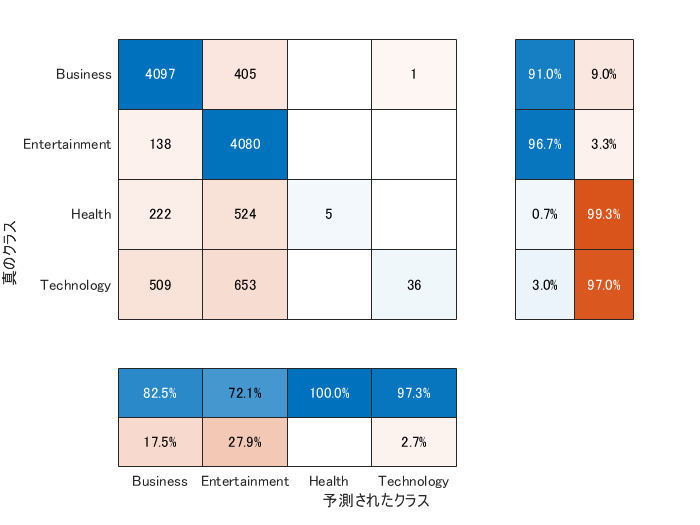

mdl2 = fitcecoc(XTrain,YTrain,'Learners',t,'Prior',"empirical",'Coding','onevsall');
categoryPred = predict(mdl2,XTrain);
confusionchart(YTrain, categoryPred, ...
    'ColumnSummary',"column-normalized",...
    'RowSummary',"row-normalized");

### Coding: "onevsall"

特に設定しなければデフォルトで "onevsone" 設定です。詳細：['Coding' — 符号化設計](https://jp.mathworks.com/help/stats/fitcecoc.html#bufm0zb-1)

これは多クラス分類を行う際に、2 値分類の手法（SVM,ロジスティック回帰）をどの使うかを指定します。

学習されたモデルの中身をみると分かりやすいのですが、"onevall" だと 

- Business vs その他

- Health vs その他

などの分類を行う 4 つの分類器が学習されていることが分かります。後ほど出てくる「効いている特徴量」などを判断するにはこちらの方がよいですね。

mdl.BinaryLearners

ans = 4×1 の cell 配列
    {1×1 ClassificationLinear}
    {1×1 ClassificationLinear}
    {1×1 ClassificationLinear}
    {1×1 ClassificationLinear}


デフォルトの "onevsone" は各クラスそれぞれを分類するモデルを作る設定ですので、結果として今回の場合は 6 つのモデルができます。以下は参考まで。

mdl3 = fitcecoc(XTrain,YTrain,'Learners',t,'Prior',"uniform",'Coding','onevsone');
mdl3.BinaryLearners

ans = 6×1 の cell 配列
    {1×1 ClassificationLinear}
    {1×1 ClassificationLinear}
    {1×1 ClassificationLinear}
    {1×1 ClassificationLinear}
    {1×1 ClassificationLinear}
    {1×1 ClassificationLinear}


## 53. 予測

52で学習したロジスティック回帰モデルを用い，与えられた記事見出しからカテゴリとその予測確率を計算するプログラムを実装せよ．

前処理して、Bag-of-Words モデルで符号化（特徴量化）して予測までを関数化します。

titles = dataTest.Title(1:2)

titles = 2×1 の string 配列
    "Study Suggests Health Insurance Saves Lives. The Hill Wonders If That's A  ..."
    "UPDATE 1-Toyota braces for stalling profit after last year's bonanza"


[class, score] = predictClassFromTitle(mdl,bag,titles)

class = 2×1 の categorical 配列
     Health 
     Business 


score =     0.6416
    0.4788


## 54. 正解率の計測

52で学習したロジスティック回帰モデルの正解率を，学習データおよび評価データ上で計測せよ．

改めて学習データの正解率から。

YPredTrain = predict(mdl,XTrain);
sum(YPredTrain == YTrain)/numel(YTrain)

ans = 0.8682

評価データについても同様に。

YTest = dataTest.Category;
[YPredTest, score] = predictClassFromTitle(mdl,bag,dataTest.Title);
sum(YPredTest == YTest)/numel(YTest)

ans = 0.8328

## ヘルパー関数

文章の前処理用関数。以下の処理をしています。

- [`tokenizedDocument`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.html) で入力文をトークン化（単語に分割）

- [`removeStopWords`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.removestopwords.html) でand, of, the などのストップワードを削除

- [`normalizeWords`](https://jp.mathworks.com/help/textanalytics/ref/normalizewords.html) で各単語を原型（？）にそろえる

- [`erasePunctuation`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.erasepunctuation.html) でコンマやピリオドなど削除

- [`removeShortWords`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.removeshortwords.html) で 2文字以下の単語を削除

- [`removeLongWords`](https://jp.mathworks.com/help/textanalytics/ref/tokenizeddocument.removelongwords.html) で 15 文字以上の単語を削除

function documents = preprocessText(textData)
    
    % Tokenize the text.
    documents = tokenizedDocument(textData);
    
    % Remove a list of stop words then lemmatize the words. To improve
    % lemmatization, first use addPartOfSpeechDetails.
    documents = addPartOfSpeechDetails(documents);
    documents = removeStopWords(documents);
    documents = normalizeWords(documents,'Style','lemma');
    
    % Erase punctuation.
    documents = erasePunctuation(documents);
    
    % Remove words with 2 or fewer characters, and words with 15 or more
    % characters.
    documents = removeShortWords(documents,2);
    documents = removeLongWords(documents,15);
    
end

文章を入力して用意したモデルで予測結果（スコア）を返す関数

function [class, score] = predictClassFromTitle(mdl,bag,title)
    documentsTest = preprocessText(title);
    XTest = encode(bag,documentsTest);
    [class,~,~,posterior] = predict(mdl,XTest);
    score = max(posterior,[],2);
end